# Create and Customize Mesh Plots with Curtains

`meshz` plots are mesh plots with a curtain around it.

### Create Data

Use `meshgrid` and `findpeaks` in a helper function to generate data for a waterfall plot.

[x,y,z] = createData();

### Basic Mesh Chart with Curtain

Plot values in matrix Z as heights above a grid in the xy-plane. The edge color varies by height in the z-direction.

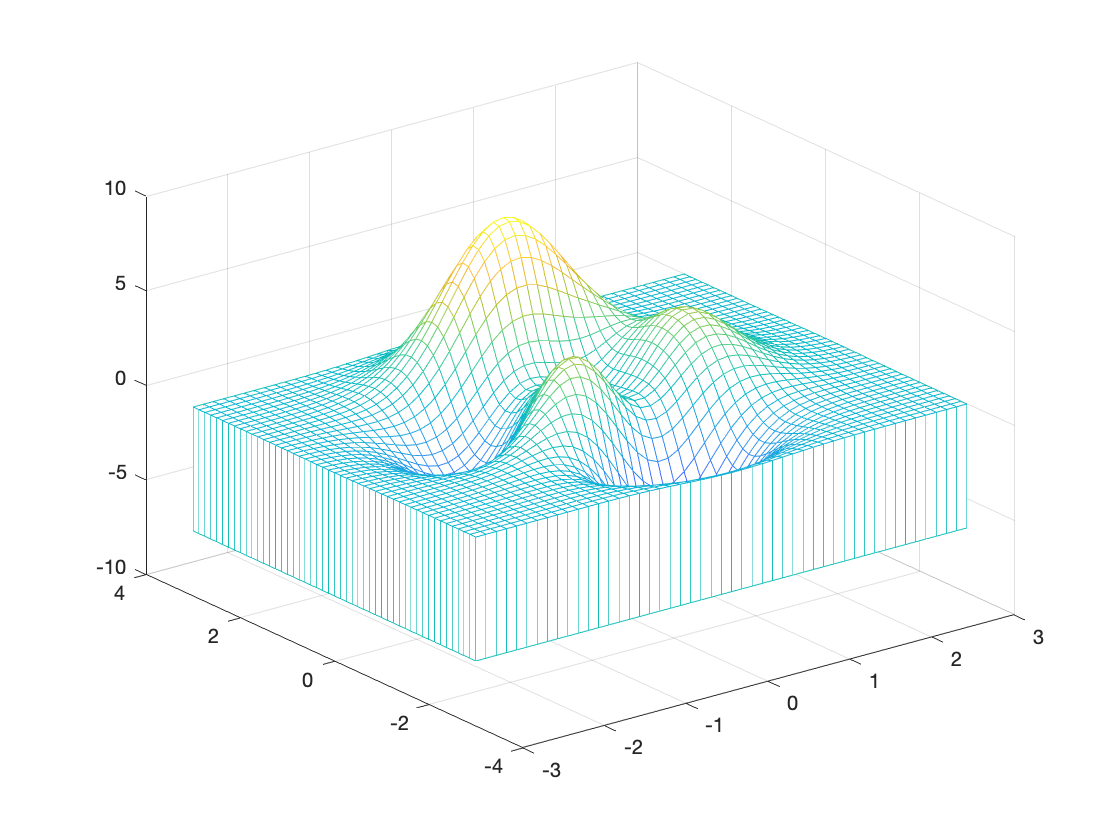

meshz(x,y,z);

## Customization

### Specify Gradient Color

The colors for the gradient of a mesh plot and surrounding curtain can be specified as the 4th input argument to `meshz`.

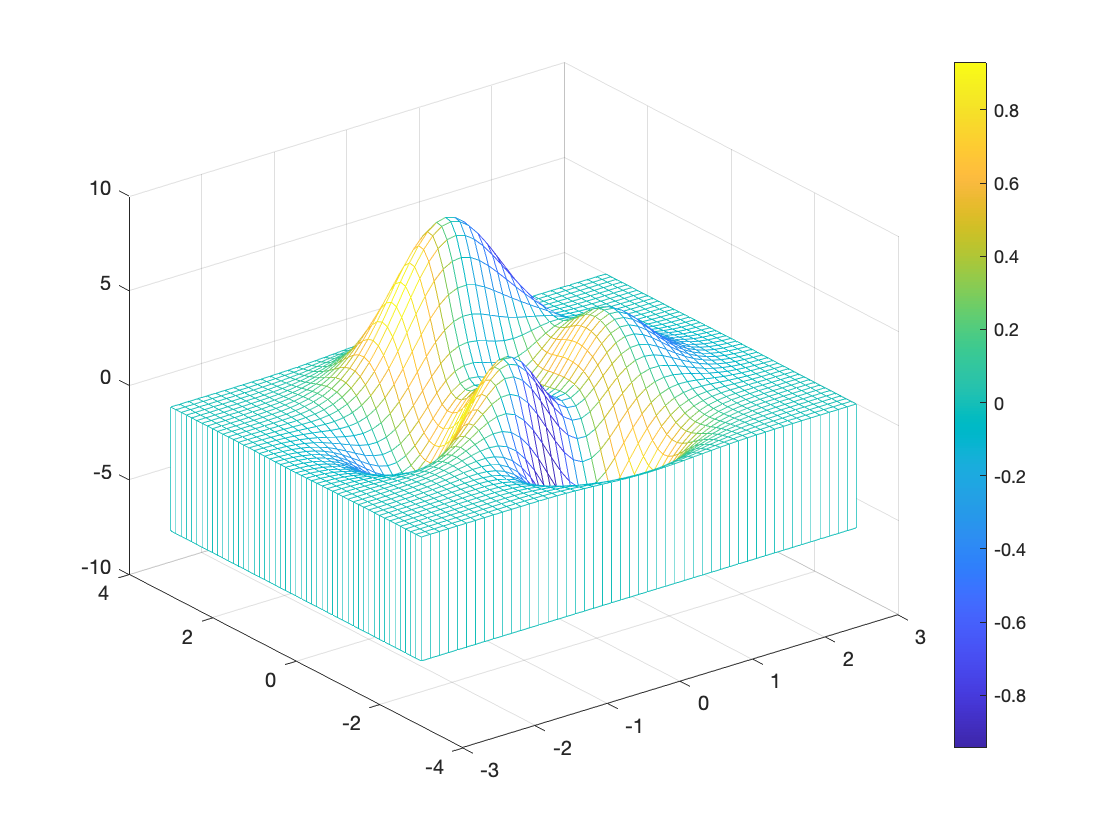

c = gradient(z);
m = meshz(x,y,z,c); % Specify the gradient as the input that determines mesh color
colorbar

### Change Plot Color

If a uniform plot color is desired, specify the desired plot color as an RGB triplet. Use `reshape` and `repmat` in a helper function to create an array of values specifying that color. This array can be used to specify the *CData* property in a Name, Value pair argument to the `set` function.

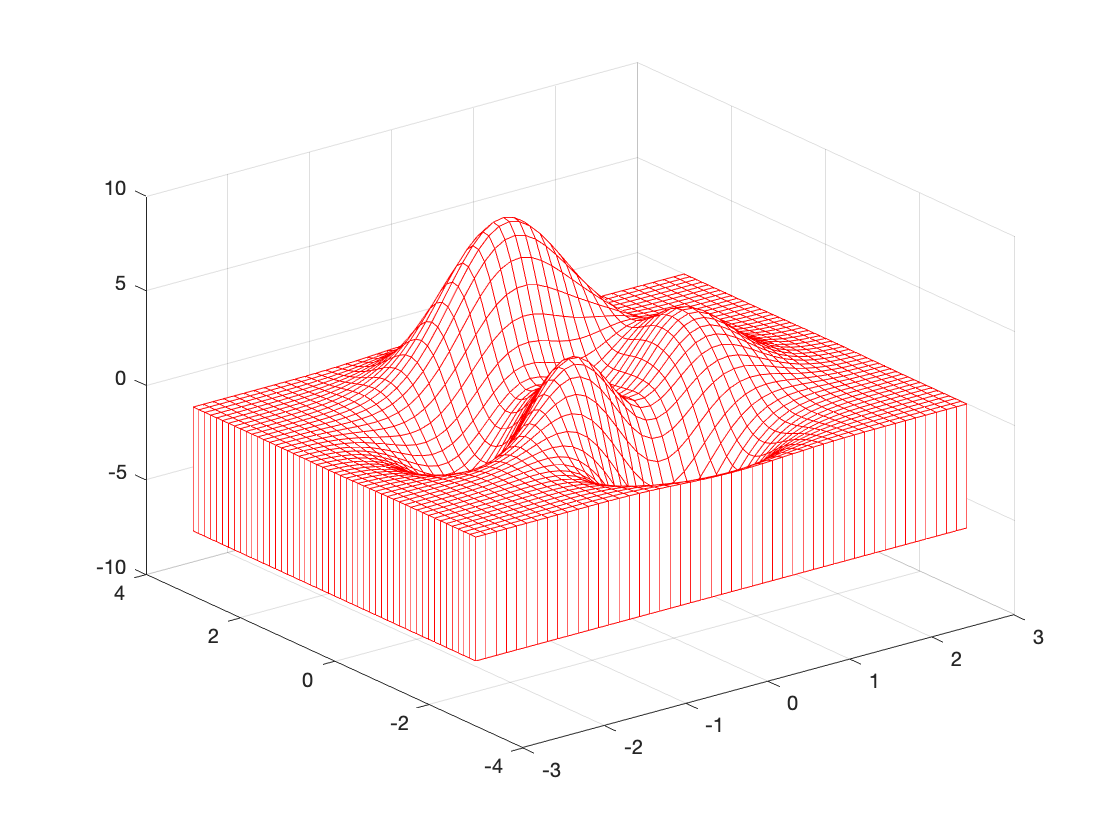

figure
m1 = meshz(x,y,z);

colorArr = createColorArr(m1, [1 0 0]);
set(m1,...              % Specify the function handle as the first argument in set
    "CData",colorArr);  % Specify vertex colors with color array

### Chang Chart Colormap and LineWidth

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. The line width of the mesh lines can modified by accessing the Surface object's *LineWidth* property using dot notation.

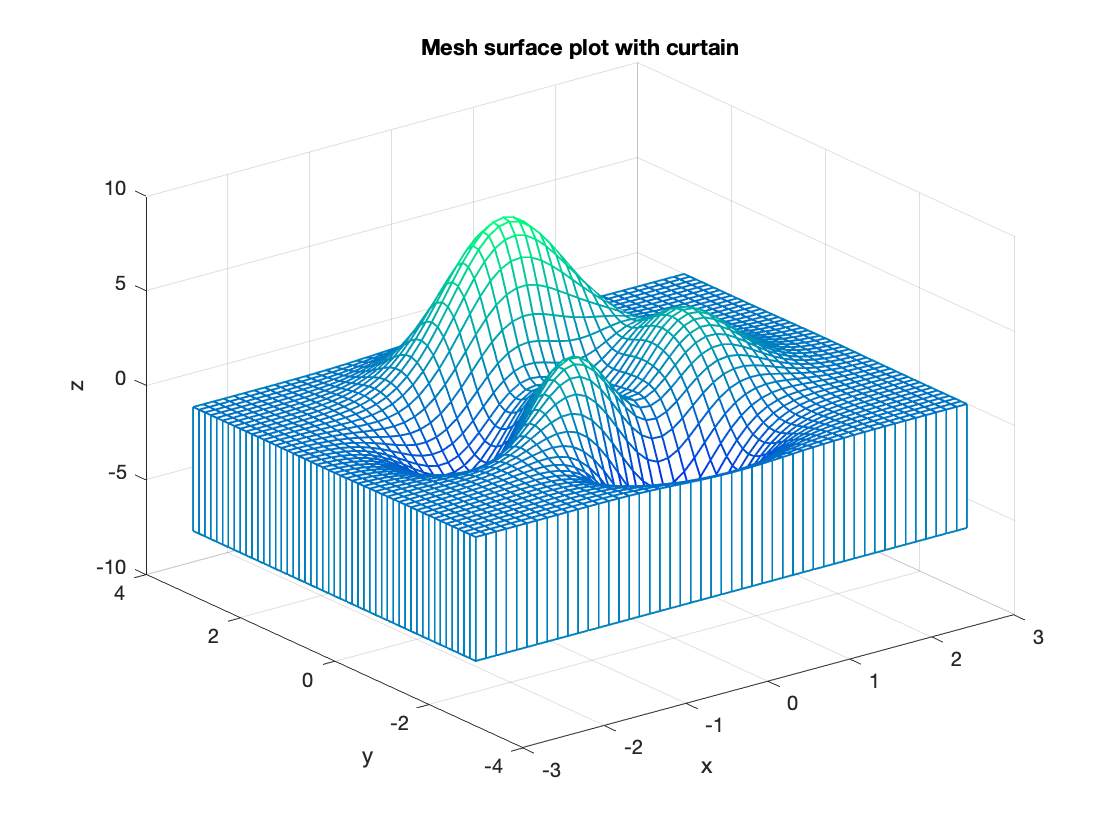

figure
m2 = meshz(x,y,z);

colormap("winter");             % Specify colormap
m2.LineWidth =1;   % Specify line width


xlabel("x"); ylabel("y"); zlabel("z");
title("Mesh surface plot with curtain");

## **Additional Information**

### **Get All Surface Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Surface, uncomment the following code. View or modify these properties using dot notation.

% get(m)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[meshz](https://www.mathworks.com/help/matlab/ref/meshz.html)

### Helper Functions

This function generates x,y, and z data using `peaks.`

function [x,y,z] = createData()
    [x,y] = meshgrid(-3:.125:3);
    z = peaks(x,y);
end


This function generates an array representing a specific color. The size of this array is the correct size to specify the *CData* property.

function colorArr = createColorArr(m, color)
    c = reshape(color,[1 1 3]);                             % Create 3-D array 
    colorArr = repmat(c,size(m.ZData,1),size(m.ZData,1),1); % Create color array using repmat
end

Copyright (c) 2021, The MathWorks, Inc.